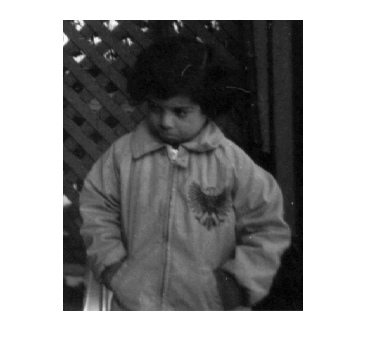

clear all;

% Load the image: 

pout = imread("pout.tif");
imshow(pout, [])

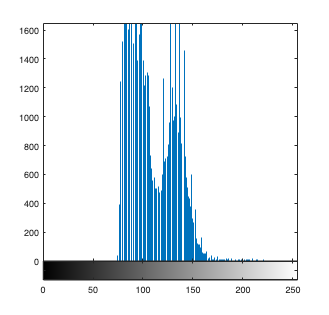


% Inspect and save the histogram:

imhist(pout);

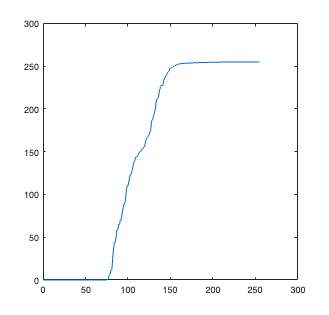

hist_initial = imhist(pout);

% Make the cumulative function:

P_x = cumsum(hist_initial);
P_x = P_x / double(numel(pout)); % Now in units of probability
P_x = P_x .* 255.;               % Now in units of graylevels

graylevels = 0:1:255;

plot(graylevels, P_x);

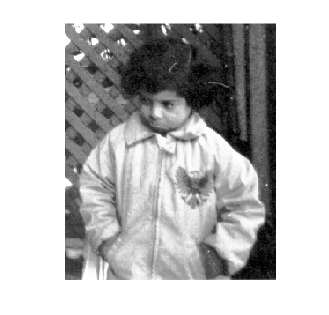


% Apply the transfer function:

pout_equalized = P_x(pout+1); % This is the important line! Why does it work? Because P_x 
% is the transfer function: new_level = f(old_level). The image is an array
% of the old levels, and therefore, insetting it to P_x will give an array
% (==image) with the new levels. 

imshow(uint8(round(pout_equalized)), [])

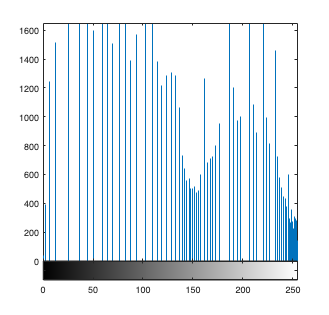


% Check the histogram:

imhist(uint8(round(pout_equalized)), 256);

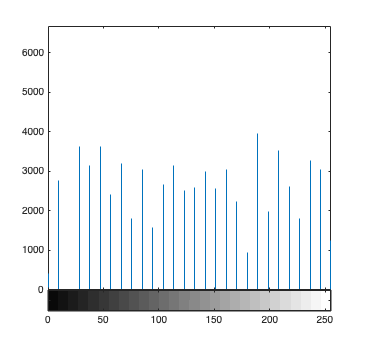

imhist(uint8(round(pout_equalized)), 28 );